# Simscape Onramp

## Module 1: Background

### What is Simscape?

Simscape is a tool that lets you rapidly create physical systems in the Simulink environment. With Simscape, you can create **physical components** (like resistors, capacitors, springs, ...) models based on physical links which are directly integrated with block diagrams and other modeling paradigms.

### **Differences with respect to Simulink**

Simscape has been developed on top of Simulink, therefore the two of them can be integrated (with some care) and the main flow stays the same. However there are conceptual differences between these two environments. Let's see them:

**1. Modeling approach**

- **Simulink** uses a **block-diagram approach** based on **signal flow**. It is ideal for modeling control systems, signal processing, and time-based dynamic systems using a top-down, algorithmic approach.

- **Simscape** uses a **physical modeling approach** based on **physical networks**. It allows you to model systems using physical connections and component-level representations, following the laws of physics directly (e.g., Kirchhoff’s laws, conservation of energy).

**3. Signal vs. Physical connections**

- In **Simulink**, blocks are connected by **unidirectional signals**, which represent data or control flow.

- In **Simscape**, components are connected by **bidirectional physical connections** (ports), which represent real-world interactions like force, current, voltage, and flow rate.

**4. Level of abstraction**

- **Simulink** is typically used at a **higher level of abstraction**, ideal for designing and simulating controllers or processing signals.

- **Simscape** provides a **lower-level, more detailed physical representation**, suitable for modeling the actual plant or environment interacting with the controller.

**5. Integration**

- **Simscape** models can be integrated into **Simulink** environments seamlessly. For example, you can use a Simulink controller to control a Simscape-modeled physical system.

- This integration supports **model-based design** workflows, enabling simulation of the complete system (controller + plant).

The main concept is that in Simscape you don't specify the equations to solve, but instad the program analyzes the physical network, determines the equations to solve and then performs the computations. Wherelse in Simulink is the user itself that defines the equations trough signals and blocks.

### Inspect data

To inspect data in Simscape you can still use the same tools as for Simulink (Scope, Data Inspector, ...) but in this case you can access data using **sensors** which work like physical sensors.

## Module 2: Mechanical example (Simscape vs. Simulink)

We are now going to simulate a **spring-mass-damper** system like the one in the figure below both in Simulink and in Simscape to see the core difference between them.

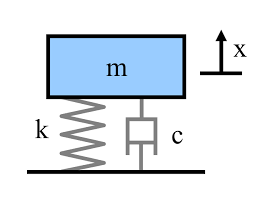

### Setup data

Since MATLAB and Simulink (and consequently Simscape) communicate we can define our setup data in MATLAB and then recall them.

clear, clc, close all

% Define the Data
m = 3.6;         % [kg]   Mass
k = 25;          % [N/m]  Stiffness
c = 3;           % [Ns/m] Damping coefficient

% Initial conditions
x0 = 0.1;        % [m]    Position
x0_dot = 0;      % [m/s]  Velocity

stopTime = 20;   % [s]    Simulation time

### SIMULINK model

The Simulink model represents a **block-based** diagram of the **equation of motion** for a system. If we assume no forces applied to the system the equation that we need to model it is


$$m \ddot{x}(t) + c \dot{x}(t) + k x(t) = 0$$


The steps we need to perform are the following:

- *Rewrite the equation so that the highest-order derivative is isolated on the left*

- *Determine the number of integrator blocks needed based on the number of variables and derivatives in the equation*

- *Add the integrators, labeling the input and output arrows*

- *Build the right-hand side of the equation using blocks*

- *Connect the remaining signals*

- *Set the initial conditions*

So the equation with the highest derivative on the left-hand side is


$$\ddot{x}(t) = -\frac{c}{m}\dot{x}(t) - \frac{k}{m} x(t)$$


Now we can start building the Simulink model: go on HOME tab and click Simulink button.

#### Run simulation

We can run the simulation in matlab and store the results to the process them

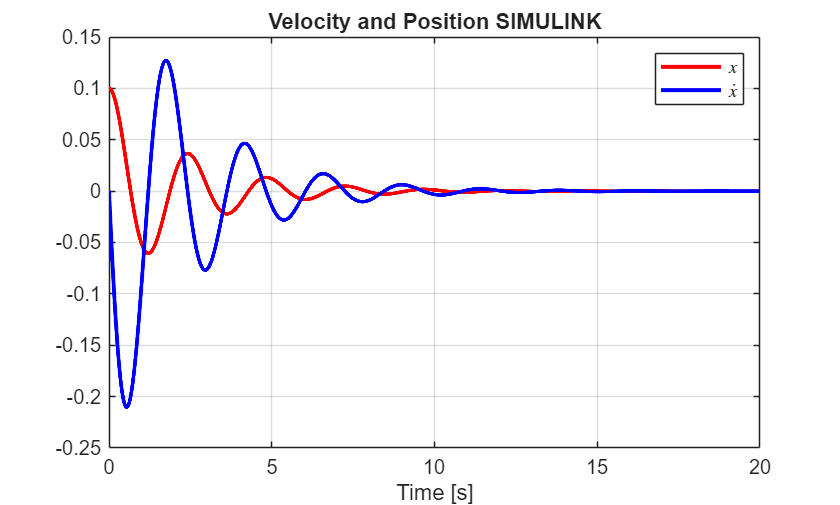

slk = sim("simulinkModelMech.slx");

% Post-processing
figure
box on, grid on
hold on
plot(slk.tout, slk.x, 'r', LineWidth=2)
plot(slk.tout, slk.x_dot, 'b', LineWidth=2)
title("Velocity and Position SIMULINK")
xlabel('Time [s]')
legend({'$x$', '$\dot{x}$'}, Interpreter="latex")

### SIMSCAPE model

Simscape lets you model physical systems using **physical network modeling**, which is more intuitive when you're dealing with mechanical, electrical, thermal, or hydraulic systems. Instead of drawing signal flow like in Simulink, you connect physical components (e.g., masses, springs, resistors) just like in real life.

The steps we need to perform are the following:

- *Drag and drop physical components into the workspace*

- *Connect the components propertly with ****physical connections***

- Add **Solver Configuration **block

- *Add ****coherent**** initial conditions*

- *Add sensors to access signals*

- *Click ****Run****, and the system will evolve according to the physical laws automatically. No need to manually rearrange or integrate the equation*

### Run simulation

We can run the simulation in MATLAB and store the results to the process them

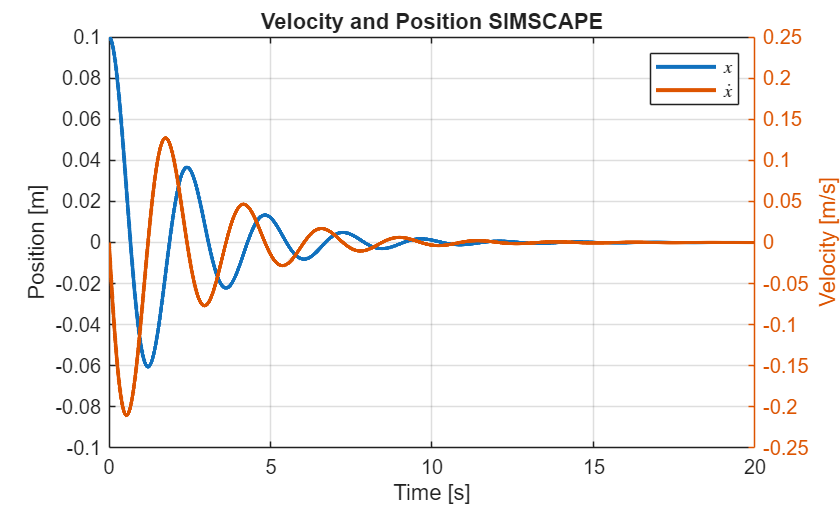

smc = sim("simscapeModelMech.slx");

% Post-processing
figure
box on, grid on
hold on
plot(smc.tout, smc.x, LineWidth=2)
ylim([-0.1, 0.1])
ylabel('Position [m]')
yyaxis("right")
plot(smc.tout, smc.x_dot, LineWidth=2)
ylim([-0.25, 0.25])
title("Velocity and Position SIMSCAPE")
xlabel('Time [s]')
ylabel('Velocity [m/s]')
legend({'$x$', '$\dot{x}$'}, Interpreter="latex")

### Comparison between Simulink and Simscape results

Let's now check if the two models are actually getting the same results: plot **1 figure **with **2 subplots **(check documentation if needed) with:

- Simulink velocity in green with dashed line and Simscape one with magenta continuous line

- Simulink position in green with dashed line and Simscape one with magenta continuous line

- Add titles

- Add legend

- Add lables to the axis

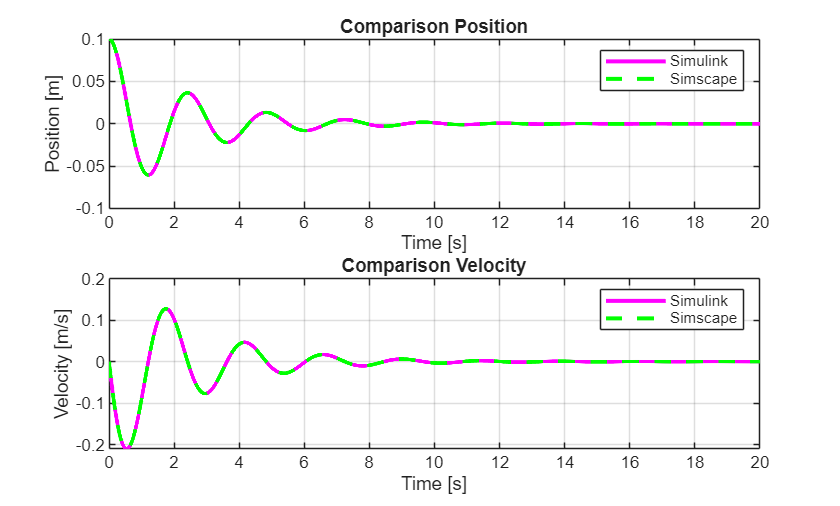

figure
subplot(2, 1, 1)
hold on
plot(slk.tout, slk.x, '-m', LineWidth=2)
plot(smc.tout, smc.x, '--g', LineWidth=2)
title("Comparison Position")
grid on, box on
legend({'Simulink', 'Simscape'})
xlabel('Time [s]')
ylabel("Position [m]")

subplot(2, 1, 2)
hold on
plot(slk.tout, slk.x_dot, '-m', LineWidth=2)
plot(smc.tout, smc.x_dot, '--g', LineWidth=2)
title("Comparison Velocity")
grid on, box on
legend({'Simulink', 'Simscape'})
xlabel('Time [s]')
ylabel("Velocity [m/s]")

Moreover, we can plot the difference between the two models:

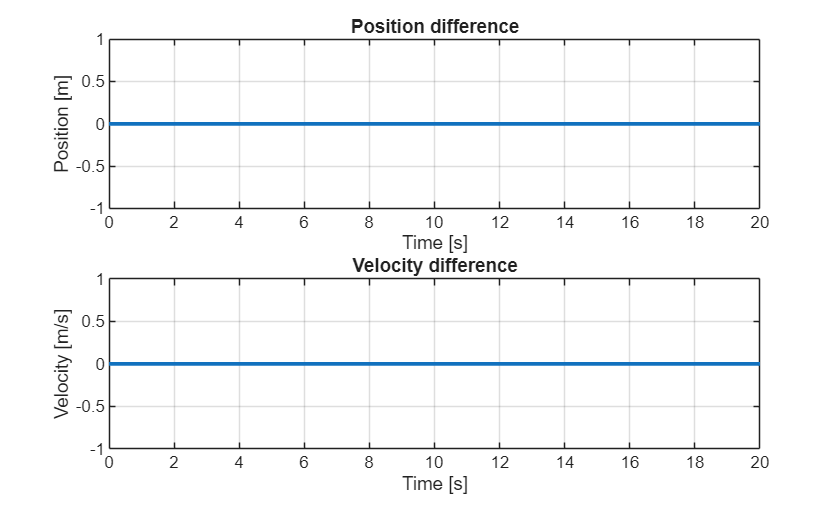

diff_pos = slk.x - smc.x;
diff_vel = slk.x_dot - smc.x_dot;

figure
subplot(2, 1, 1)
plot(slk.tout, diff_pos, LineWidth=2)
title("Position difference")
grid on, box on
xlabel("Time [s]")
ylabel("Position [m]")

subplot(2, 1, 2)
plot(slk.tout, diff_vel, LineWidth=2)
title("Velocity difference")
grid on, box on
xlabel("Time [s]")
ylabel("Velocity [m/s]")

As expected, the difference both in position and velocity is exactly zero!

## Module 3: Electrical example (Simscape) - Solar cell of a spacecraft in LEO orbit

Simulate a solar cell receiving irradiance from the Sun in a Low Earth Orbit (LEO) and producing electricity toward a battery.

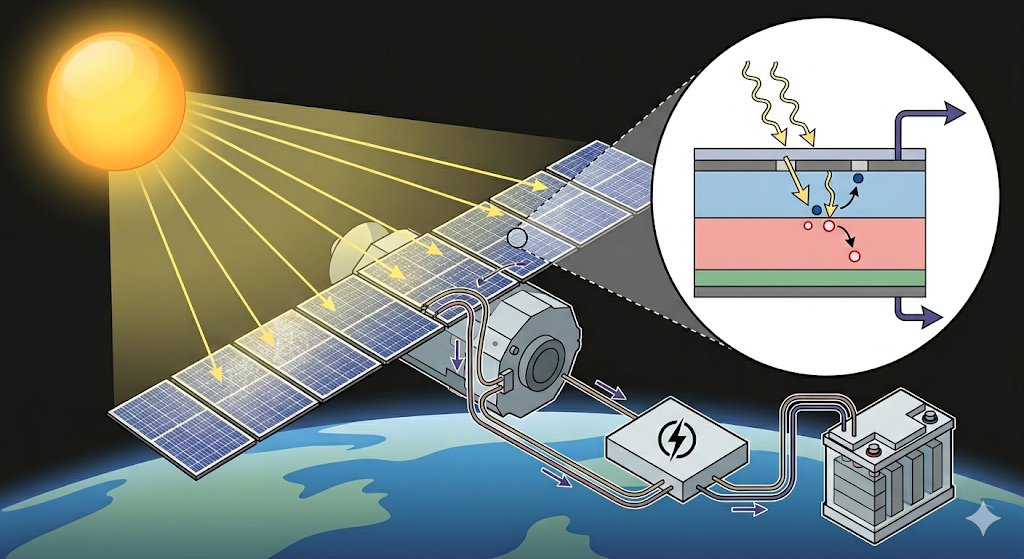

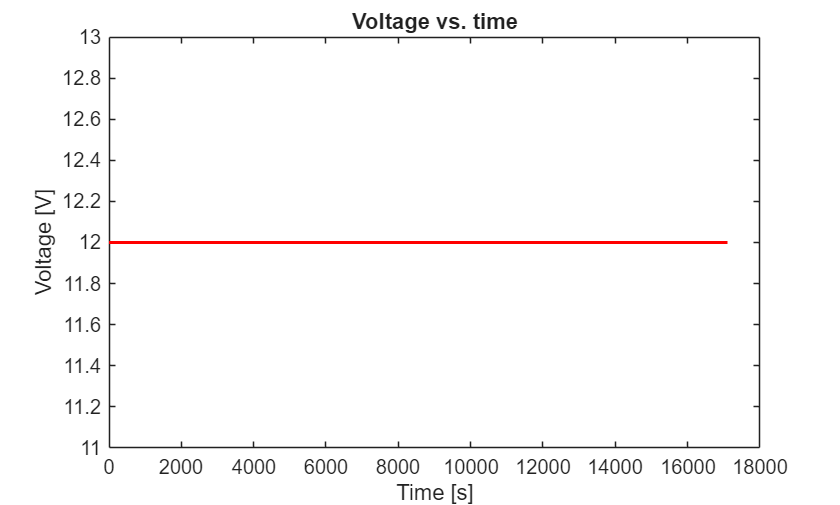

Ir = 1361;         % [W/m^2] Solar irradiance
T_orb = 95*60;     % [s]     Orbital period (LEO)
freq = 2*pi/T_orb; % [rad/s] Frequency
simTime = 3*T_orb; % [s]     Simulation time

smcSolarCell = sim("simscapeSolarCell.slx");

% Post-processing
figure
box on, grid on
plot(smcSolarCell.tout, smcSolarCell.V, 'r', LineWidth=2)
xlabel('Time [s]')
ylabel('Voltage [V]')
title("Voltage vs. time")

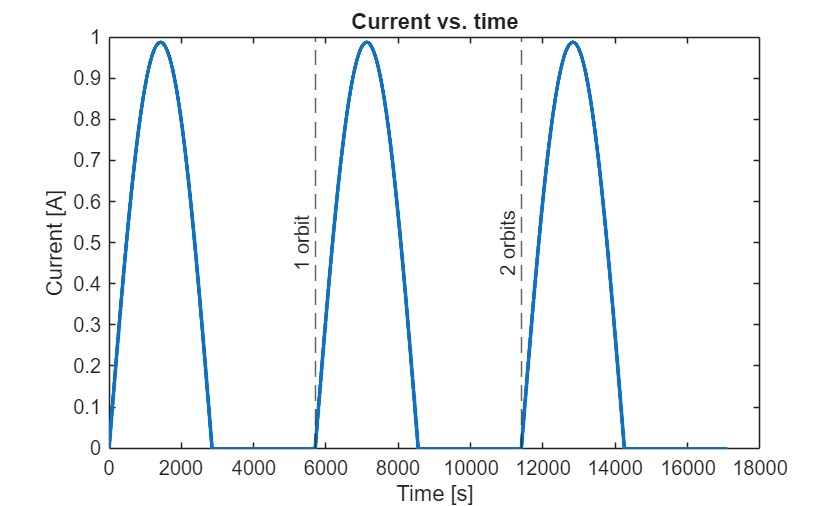

figure
plot(smcSolarCell.tout, smcSolarCell.I, LineWidth=2)
hold on
xline(T_orb, '--', '1 orbit', 'LabelHorizontalAlignment','left', 'LabelVerticalAlignment','middle')
xline(2*T_orb, '--', '2 orbits', 'LabelHorizontalAlignment','left', 'LabelVerticalAlignment','middle')
xlabel('Time [s]')
ylabel('Current [A]')
title("Current vs. time")

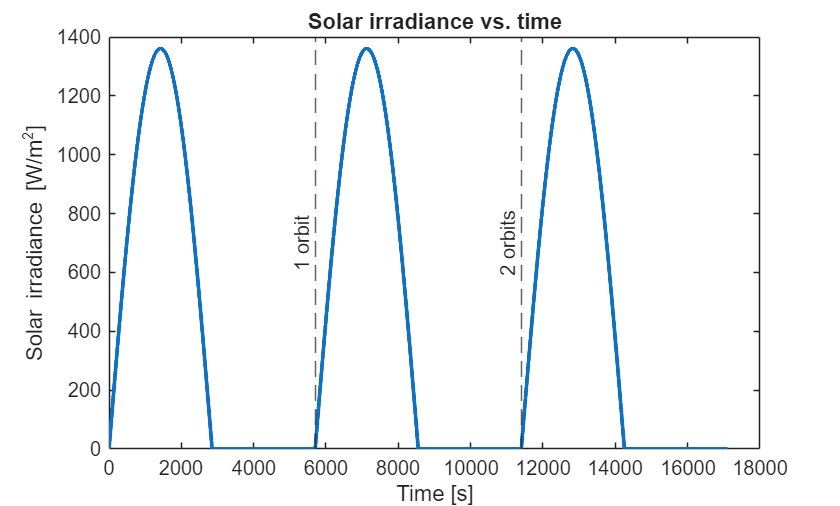

figure
plot(smcSolarCell.tout, smcSolarCell.Ir, LineWidth=2)
xline(T_orb, '--', '1 orbit', 'LabelHorizontalAlignment','left', 'LabelVerticalAlignment','middle')
xline(2*T_orb, '--', '2 orbits', 'LabelHorizontalAlignment','left', 'LabelVerticalAlignment','middle')
xlabel('Time [s]')
ylabel('Solar irradiance [W/m^2]')
title("Solar irradiance vs. time")

## Module 4: Thermal example (Simscape) - Heat Conduction Through Iron Rod

This example shows how thermal blocks can model a long iron rod that is fixed to a hot base at one end and exposed to air along its length and at its free end. The rod is an extended surface that undergoes conduction along its length and convection with air in the direction perpendicular to its length. Extended surfaces are often used as fins to cool a solid.

In this scenario, the base is fixed to a wall with a temperature of 100 degrees Celsius. Heat transfers down the rod through conduction, gradually heating the rod's thermal mass. Heat escapes the rod cylindrical surface and free end through natural convection with ambient air that has a temperature of 20 degrees Celsius. The entire rod temperature initially equals the ambient air temperature. The temperature along the rod reaches steady state after approximately 1500 seconds. The rod is made of iron, is 20 cm in length and 2.5 cm in diameter.

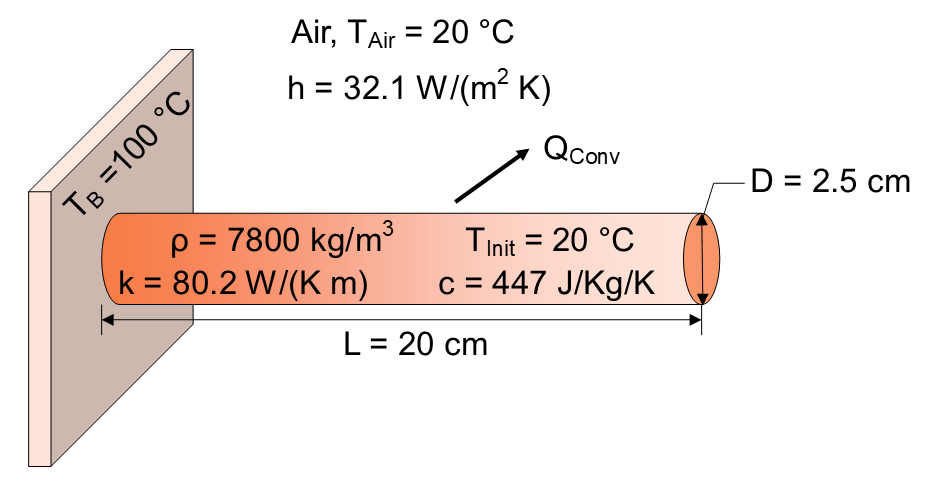

## Theoretical framework

### Law of Energy Conservation

The first law of thermodynamics is a fundamental principle in physics stating that the total energy of an isolated system remains constant over time. This law is expressed mathematically in terms of power as,

$\frac{dU}{dt} = Q - W$.

Where:

- $\frac{\textrm{dU}}{\textrm{dt}}$ is the rate of change in internal energy with respect to time (measured in *W* in SI units).

- $Q$ is the rate of heat added to the system (measured in *W*).

- $W$ is the rate of work done by the system (measured in *W*).

In thermal systems where no work occurs, the rate of change in internal energy equals the rate of heat added to the system,

$\frac{dU}{dt} = Q $.

In the iron rod, conduction and convection heat transfer ($Q$) change the internal energy stored in the rod's thermal mass ($U$).

### Conduction

Thermal conduction is the process of heat transfer through a material. When the material is heated, its molecules gain kinetic energy, leading to increased motion. This heightened motion causes collisions with neighboring molecules, transferring energy in the process. This transfer continues until thermal equilibrium is achieved, resulting in a uniform temperature throughout the substance.

The thermal conduction equation, also known as Fourier's law, describes the rate of heat transfer through a material,

$Q =k \frac{A}{L} (T_1 - T_2)$,

where:

- $Q$ is the heat flow from end $1$ to end $2$ (measured in W).

- $k$ is the thermal conductivity of the material (measured in *W/(K m)*).

- $A$ is the area normal to the heat flow direction (measured in *m^2*).

- $L$ is the thickness in the heat flow direction (measured in *m*).

- $T_1$ and $T_2$ are the temperatures at either end of the conductive heat transfer element (measured in *degC*).

### Convection

Convection is the process of heat transfer through the movement of a fluid. The movement of fluid combined with conduction leads to the transport of heat energy from hotter regions to cooler regions within the fluid. Natural convection occurs in a fluid due to density differences caused by temperature gradients. When a fluid is heated, it becomes less dense and tends to rise, while cooler, denser fluid moves in to replace it. This sets up a circulation pattern within the fluid, where heat is transported from hotter regions to cooler regions.

The thermal convection equation, known as Newton's law of cooling, describes the rate of heat transfer from a surface to the surrounding fluid,

$Q =h  A _{Conv}(T_1 - T_2)$,

where:

- $h$ is the convective heat transfer coefficient (measured in *W/(K m^2)*).

- $A_{\textrm{Conv}}$ is the surface area (measured in *m^2*).

- $T_1$ and $T_2$ are the temperatures of the surface and surrounding fluid, respectively (measured in *degC*).

### Thermal Mass

Thermal mass reflects a material's ability to store and release heat energy. The change in internal energy of a thermal mass is represented by the equation,

$\frac{dU}{dt}= c  m \frac{dT}{dt}$,

where:

- $\frac{\textrm{dU}}{\textrm{dt}}$ is the rate of change in internal energy with respect to time (measured in *W*). 

- $c$ is the specific heat of the material (measured in *J/(Kg K)*).

- $m$ is the mass (measured in *kg*).

- $T$ is the temperature (measured in *degC* or *K*).

The rate of change in internal energy of the material, $U$, is proportional to its rate of change in temperature, $T$. The specific heat capacity, $c$, represents the amount of energy required to change the temperature of a unit mass of the material by one degree. Large thermal mass, $\textrm{cm}$,  slows down temperature changes in a system.

## Simscape implementation: Lumped-mass Rod with Transient Thermal Behavior

Combine conductive, convective, and thermal mass elements to fully model the rod with transient behavior. The rod has a base temperature of 100 degrees Celsius. The rod undergoes conduction along its length as well as natural heat convection with air along its length and at its tip. The rod temperature is initially equal to the ambient air temperature of 20 degrees Celsius.

In the Rod model, an intermediate node between two equally divided Conductive Heat Transfer elements represents the rod midpoint. A single thermal mass at the intermediate node models the entire rod mass as maintaining the midpoint temperature. Convective heat transfer elements model convection from the rod cylindrical surface and rod endpoint to the surrounding atmosphere.

Using the first law of thermodynamics, the rate of change in internal energy of the thermal mass equals the net heat flow through the intermediate node:

$\frac{dU}{dt} = Q $.

Net heat flow into the node is due to conduction from the base, convection with the air along the cylindrical surface, and conduction/convection at the rod tip:

$Q = Q_{Left} + Q_{Cyl} + Q_{Right} $.

On the left side of the intermediate node, the heat flows into the node due to conduction from the base:

$Q_{Left} = k \frac{2A}{L}(T_{Base} - T)$,

where $T$ is the temperature of the intermediate node.

Along the cylindrical surface of the rod, heat flows out of the node due to convection with the air:

$Q_{Cyl} = h A_{Cyl}(T_{Air} - T)$.

On the right side of the intermediate node, heat flows out through conduction in the rod and then by convection between the rod tip and air:

$Q_{Right} = k \frac{2A}{L}(T_{End} - T)$,

$Q_{Right} = h A(T_{Air} - T_{End})$,

where $T_{\textrm{End}}$ is the temperature of the rod tip, corresponding to the junction of the *Conduction1B *B port and the *Convection End* A port in the Simscape™ model. Rearrange the $Q_{\textrm{Right}}$ equations to eliminate $T_{\textrm{End}}$:

$Q_{Right} = \frac{2Akh(T_{Air} - T)}{Lh + 2k}$.

Substituting the heat flow expressions and thermal mass internal energy change expression into the energy conservation equation results in the governing differential equation for temperature of the rod, $T$:

$ c m \frac{dT}{dt} = k \frac{2A}{L}(T_{Base} - T) + h A_{Cyl}(T_{Air} - T) + \frac{2Akh( T_{Air} - T)}{Lh + 2k}$.

The Simscape network sums heat transfer at the nodes and is equivalent to this differential equation.

### Set the needed parameters

clear, clc, close all
% Model parameters

% Thermal conditions
T_air     = 20;        % Air temperature           [degC]
T_base    = 100;       % Base temperature          [degC]
T_init    = T_air;     % Initial rod temperature   [degC]

% Geometric parameters
L         = 0.2;       % Rod length                [m]
D         = 0.025;     % Rod diameter              [m]
A         = pi*D^2/4;  % Rod cross-sectional area  [m^2]
A_cyl     = pi* D * L; % Rod cylindrical surface area [m^2]

% Iron material properties
rho       = 7800;      % Iron density              [Kg/m^3]
k         = 80.2;      % Iron thermal conductivity [W/(K*m)]
h         = 32.1;      % Convective heat transfer coefficient [W/(m^2*K)]
c         = 447;       % Iron specific heat [J/kg/K]

m         = rho*A*L;   % Rod mass [kg]

### Run the simulation

smcRod = sim("simscapeRod.slx");

### Post-processing

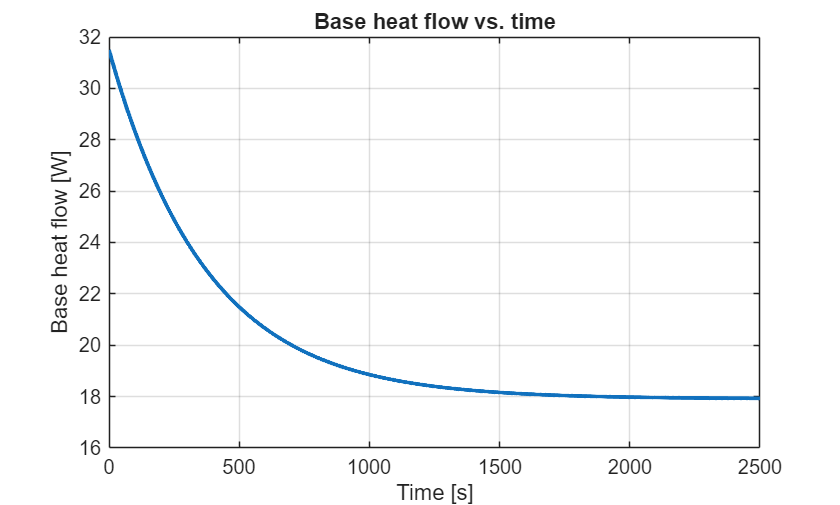

figure
plot(smcRod.tout, smcRod.Q_B, LineWidth=2)
xlabel('Time [s]')
ylabel('Base heat flow [W]')
title("Base heat flow vs. time")
box on, grid on

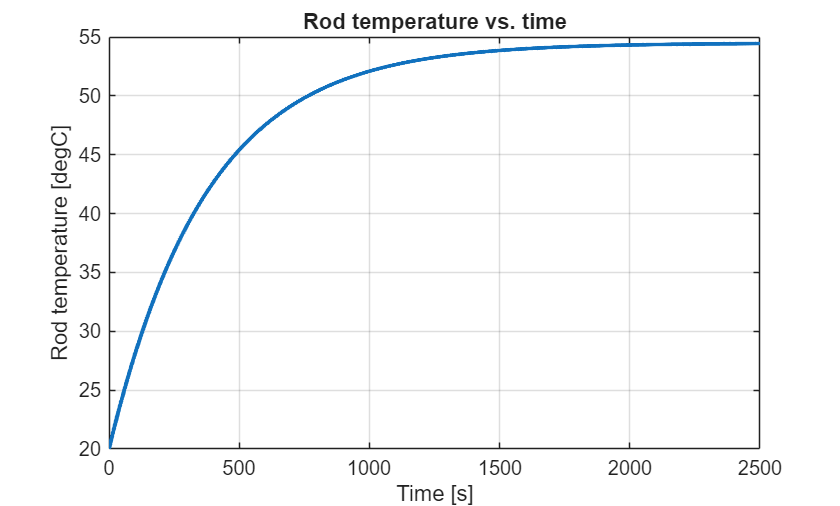

figure
plot(smcRod.tout, smcRod.T_L, LineWidth=2)
xlabel('Time [s]')
ylabel('Rod temperature [degC]')
title("Rod temperature vs. time")
box on, grid on